## Forward Euler

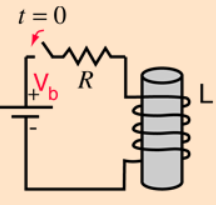

The KVL equations for the above circuit can be written as,


$$V_b -V_R -V_{L\;} =0$$


where $V_b$ is the source voltage, $V_R$  is the voltage across the resistor, $V_{L\;}$ is the votage across the inductor. We know that the voltage accross resistor and inductor at a given value of time is given by,  $V_R = I(t) R$ and $V_L = L \frac{d}{dt} I(t)$, respectively. Thus the above equation becomes,


$$V_{b\;} -I\left(t\right)\;R-L\;\frac{\mathrm{d}}{\mathrm{d}t}I\left(t\right)\;$$


As discussed in the lecture the first step in obtaining numerical soluton to Initial Value Problems is to descretize the problem at various steps of time.

## 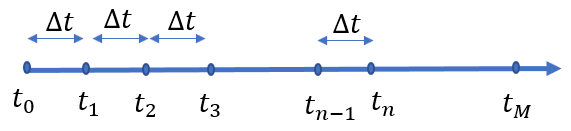

Then, write the above eqaution at time point $t=t_n$,


$$V_{b\;} -I\left(t_{n\;} \right)R-L\;\frac{\textrm{dI}\left(t_n \right)}{dt}=0$$


$I\left(t_{n\;} \right)$ is the current at time point, $t=t_n$,  for the ease of notation let's use$\;I_n$  to denote $I\left(t_{n\;} \right)$. Using this the above equation becomes,


$$V_{b\;} -I_n \;R-L\;\frac{dI_n }{dt}=0$$


To find the solution to the above equation, we use the Forwad Euler approximation for$\;\;\frac{{\textrm{dI}}_n }{dt}$


$$\frac{dI_n }{dt}=\frac{I_{n+1} -I_n }{\Delta t}$$


Subsitute this in the KVL equation we obtain the following **difference equation**,


$$V_{b\;} -I_n \;R-L\left(\frac{I_{n+1} -I_n }{\Delta t}\right)=0$$



$$\frac{L}{\Delta t}\;I_{n+1} =V_{b\;} -I_n \;R+L\frac{I_n }{\Delta t}$$


=> $\;I_{n+1} =\frac{\Delta \;t}{L}\left(V_{b\;} -I_n \;R+L\frac{I_n }{\Delta t}\right)$

Suppose we need to find, $I_1$, i.e. the current $t=t_1$, we write the above equation to find the current $I_1$


$$\;I_1 =\frac{\Delta \;t}{L}\left(V_{b\;} -I_0 \;R+L\frac{I_0 }{\Delta t}\right)$$


As we can see from the above equation we need the current $I_0$ to find $I_1$. We need the  initial value of the current $I_0$ to solve the problem, suppose it was given that the $I_0 =0$, the the solution becomes,


$$\;I_1 =\frac{\Delta \;t}{L}\left(V_{b\;} \right)$$


Now that we have solved the problem at $t=t_1$, we proceed to solve this problem at nect time point, $t=t_2$

                                                         
$$\;I_2 =\frac{\Delta \;t}{L}\left(V_{b\;} -I_1 \;R+L\frac{I_1 }{\Delta t}\right)$$
    

As expected the solution at $t_2$ depends on solution at previous time point, $t_1$. Therefore, we substiute the solution found for $I_1$ in the above equation.

The following code solves the above ODE problem,

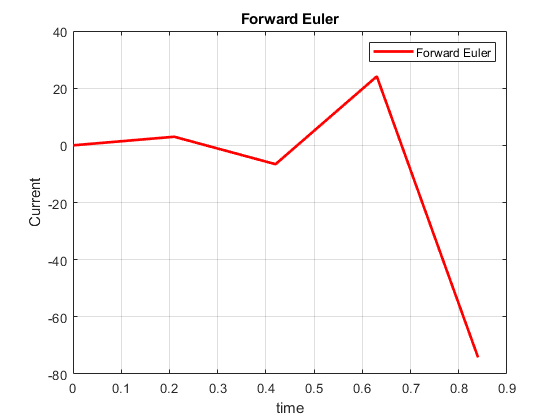

clear all
Vb = 5;
R = 7;
L = 0.35;

dT =0.1; % time step
Tfe = 0:dT:0.9; % descritised time points. 
% % T contains different time points. T = [ t0 t1 t2 ...]
% % T = [ 0 dT 2*dT 3*dT ... ]
% % t0 = 0; t1 = dT; t2 =2dT, etc 
Ife(1) = 0; % initial condition
for n=2:length(Tfe)
%     I(t) = (dT/L)*(Vb  - I(t-1)*R +  L/dT *I(t-1)  );
      Ife(n) = ((dT/L)*Vb  - (dT/L)*Ife(n-1)*R +  Ife(n-1)  );
end

figure()
grid on 
plot(Tfe,Ife ,'r','linewidth',2,'displayname','Forward Euler');
hold on

title('Forward Euler')
legend
grid on
xlabel('time')
ylabel('Current')

%  ylim([0 0.7])

        1 . As seen above, the accuracy of the above problem changes at different time steps. The solutions are more accurate at smaller time steps. Why?

         2.  Also, at time step, $\Delta t =0.07$or above , the Forward Euler approximation for $\frac{d I_n}{dt}$ gives completely inaccurate solutions. Why?

## ODE: Backward Euler

The KVL equations for the above circuit can be written as,


$$V_b -V_R -V_{L\;} =0$$


where $V_b$ is the source voltage, $V_R$  is the voltage across the resistor, $V_{L\;}$ is the votage across the inductor. We know that the voltage accross resistor and inductor at a given value of time is given by,  $V_R = I(t) R$ and $V_L = L \frac{d}{dt} I(t)$, respectively. Thus the above equation becomes,


$$V_{b\;} -I\left(t\right)\;R-L\;\frac{\mathrm{d}}{\mathrm{d}t}I\left(t\right)\;$$


As discussed in the lecture the first step in obtaining numerical soluton to Initial Value Problems is to descretize the problem at various steps of time.

Then, write the above eqaution at time point $t=t_n$,


$$V_{b\;} -I\left(t_{n\;} \right)R-L\;\frac{\textrm{dI}\left(t_n \right)}{dt}=0$$


$I\left(t_{n\;} \right)$ is the current at time point, $t=t_n$,  for the ease of notation let's use$\;I_n$  to denote $I\left(t_{n\;} \right)$. Using this the above equation becomes,


$$V_{b\;} -I_n \;R-L\;\frac{dI_n }{dt}=0$$


To find the solution to the above equation, we use the approximation for$\;\;\frac{{\textrm{dI}}_n }{dt}$


$$\frac{dI_n }{dt}=\frac{I_n -I_{n-1} }{\Delta t}$$


Subsitute this in the KVL equation we get the following **difference equation**,


$$V_{b\;} -I_n \;R-L\;\left(\frac{I_n -I_{n-1} }{\Delta t}\right)=0$$


Rearranging this to solve for $I_n$ we get,


$$I_n \;R+L\;\frac{I_n }{\Delta t}=V_b +L\frac{I_{n-1} }{\Delta t}$$



$$\left(R+\;\frac{L}{\Delta t}\right)I_n =V_b +L\frac{I_{n-1} }{\Delta t}$$


Suppose we need to find, $I_1$, i.e. the current $t=t_1$, we write the above equation to find the current $I_1$


$$\left(R+\;\frac{L}{\Delta t}\right)I_1 =V_b +L\frac{I_0 }{\Delta t}$$


As we can see from the above equation we need the current $I_0$ to find $I_1$.

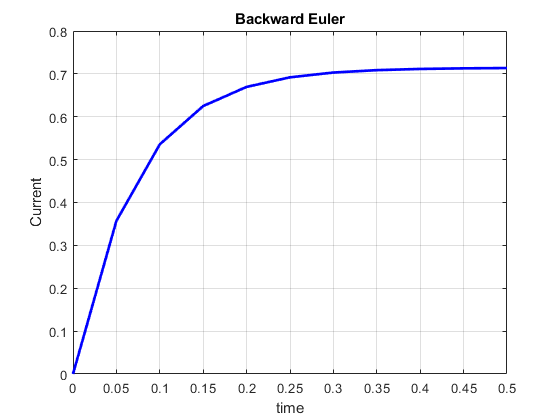

 clear all
Vb = 5;
R = 7;
L = 0.35;
dT =0.05; %sec
T = 0:dT:0.5;
Ibe(1) = 0;
for n=2:length(T)
    
    Ibe(n) = (1/(R + L/dT)) *(Vb + (L/dT)*Ibe(n-1));
end
 figure()
plot(T,Ibe,'b','LineWidth',2,'displayname','Backward Euler')
hold on 
% plot(T,Ife,'b','LineWidth',2, 'displayname','Forward Euler')
grid on
xlabel('time')
ylabel('Current')
title('Backward Euler')
ylim([0 0.8])

Unlike Forward Euler  Method, the  Backward Euler method is ALWAYS stable.   However, the accuracy of the BE method is affected by the step size, $\Delta t$. 

Although, a higher accuracy can be achieved by using a smaller time step, $\Delta t$, however, this increases the number of time steps. Thus, increasing the computation time.

## Second-Order ODE's 

Suppose you are given the following  second order ODE,


$$\ddot{y} + 5\dot y + 6y = 10sin(t)$$
 

We know how to solve the first oder ODEs. Therefore, we start by  transforming the equation into two 1st-order ODEs.

Let's introduce two new variables, $x_1$ and  $x_2$. Where, $x_1 = y$. The given equation can be written in terms of $x_1$ as,


$$\ddot{x_1} + 5\dot x_1 + 6x_1 = 10sin(t)$$


Now let's use the second variable, $x_2$. We can set $x_2$ to be the derivative of $x_1$,

$x_2  = \dot x_1$  or   $\dot x_1  = x_2$

Using this our equation becomes,


$$\dot{x_2} + 5 x_2 + 6x_1 = 10sin(t)   $$
   
$$<=>$$
 
$$\dot{x_2} =- 6 x_1 - 5x_2 + 10sin(t)$$
   

Now, we have following two equations,


$$\dot x_1(t)  = x_2(t)$$



$$\dot{x_2 (t)} =- 6 x_1(t) - 5x_2(t) + 10sin(t)$$


The above can be witten in form of the matrix equation as,


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \left(t\right)\\
\dot{x_2 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-6 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
10\;\sin \left(t\right)
\end{array}\right\rbrack$$


The above system is a first order ODE, which can be solved using the integration methods we studied earlier. We can write the above system in more compact form as

$\underset{\dot{\;\mathit{\mathbf{X}}} \left(t\right)}{\underbrace{\left\lbrack \begin{array}{c}
\dot{x_1 } \left(t\right)\\
\dot{x_2 } \left(t\right)
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{cc}
0 & 1\\
-6 & 5
\end{array}\right\rbrack } \;\;} \underset{\mathit{\mathbf{X}}\left(t\right)}{\underbrace{\left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)
\end{array}\right\rbrack } } +\underset{\mathit{\mathbf{B}}\left(t\right)}{\underbrace{\left\lbrack \begin{array}{c}
0\\
10\;\sin \left(t\right)
\end{array}\right\rbrack } }$       -- (1)


$$\dot{\;\mathit{\mathbf{X}}} \left(t\right)=\mathit{\mathbf{M}}\;\mathit{\mathbf{X}}\left(t\right)+\mathit{\mathbf{B}}\left(t\right)$$
 

At $t=t_n$, $\dot{\;{\mathit{\mathbf{X}}}_n } =\mathit{\mathbf{M}}\;{\mathit{\mathbf{X}}}_n +{\mathit{\mathbf{B}}}_n$

We can use the  backward euler approximation for the derivatives term as 


$${\dot{\mathit{\mathbf{X}}} }_n \approx \frac{{{\mathit{\mathbf{X}}}_n -X}_{n-1\;} }{\Delta t}$$


We can subsitute this approximation for the derivativee in equation (1)  to obtain the difference equation

$\frac{{{\mathit{\mathbf{X}}}_n -\mathit{\mathbf{X}}}_{n-1\;} }{\Delta t}\;=\mathit{\mathbf{M}}\;{\mathit{\mathbf{X}}}_n +{\mathit{\mathbf{B}}}_n$      <=> $\left(\frac{\mathit{\mathbf{I}}}{\Delta t}\;-\mathit{\mathbf{M}}\right)\;\;{\mathit{\mathbf{X}}}_n =\;{\mathit{\mathbf{B}}}_n +\frac{{\mathit{\mathbf{X}}}_{n-1} }{\Delta t}$

$\mathit{\mathbf{I}}$ is the identity matrix of size 2x2. We can solve the above difference equation for $\textbf X_n$ for all time points.

clear all

dT =0.09; %sec
T = 0:dT:3; % discritise T as T = [t0 t1 t2 ... ]
% Initial Condiiton
X(:,1) = [0; 5];
M = [ 0 1; -6 -5];
M_tilde = -M + (1/dT)*eye(2);

% At t = t1
  B= [0; 10*sin(T(2))];
 X(:,2) = M_tilde\(B + X(:,1)/dT);
 
% At t = t2
  B= [0; 10*sin(T(3))];
 X(:,3) = M_tilde\(B + X(:,2)/dT);
 
 % At t = t3
  B= [0; 10*sin(T(4))];
 X(:,4) = M_tilde\(B + X(:,3)/dT);
 
  % At t = t4
  B= [0; 10*sin(T(5))];
 X(:,5) = M_tilde\(B + X(:,4)/dT);
 
 %  repeat for all the time points
 
 y_exact = -6*exp(-3*T) + 7*exp(-2*T) + sin(T) - cos(T);
 figure()
plot(T,X(1,:),'b-*','LineWidth',2,'displayname','Backward Euler')

Error using plot
Vectors must be the same length.

hold on 
plot(T,y_exact,'r--','LineWidth',2,'displayname','Exact Solution')
xlabel('time')
ylabel('y')
grid on
legend("Location","best")